Variables

R = 75

R = 75

L = 1

L = 1

C = 1

C = 1

System input output

syms i(t)
syms v(t)

Equation

ode = (1/C)*diff(i,t) == diff(v,t,2) + (1/(R*C))*diff(v,t) + (1/(L*C))*v

$$ode(t) = \frac{\partial }{\partial t}i\left(t\right)=\frac{\partial^{2}}{\partial t^{2}}v\left(t\right)+\frac{\frac{\partial }{\partial t}v\left(t\right)}{75}+v\left(t\right)$$

Initial conditions

condition1 = i(0) == 3

$$condition1 = i\left(0\right)=3$$

condition2 = v(0) == 6

$$condition2 = v\left(0\right)=6$$


conds = [condition1,condition2]

$$conds = \left(\begin{array}{cc} i\left(0\right)=3 & v\left(0\right)=6 \end{array}\right)$$


Sol(t) = dsolve(ode,conds)

 
Sol(t) =
 
[ empty sym ]
 


Sol = simplify(Sol)

 
Sol(t) =
 
[ empty sym ]
 


Plotting

(temp values just for testing plot code)

tempT = [0:0.5:10]

tempT =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


fakeV = [0,3,8,9,7,13,16:30]

fakeV =      0     3     8     9     7    13    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


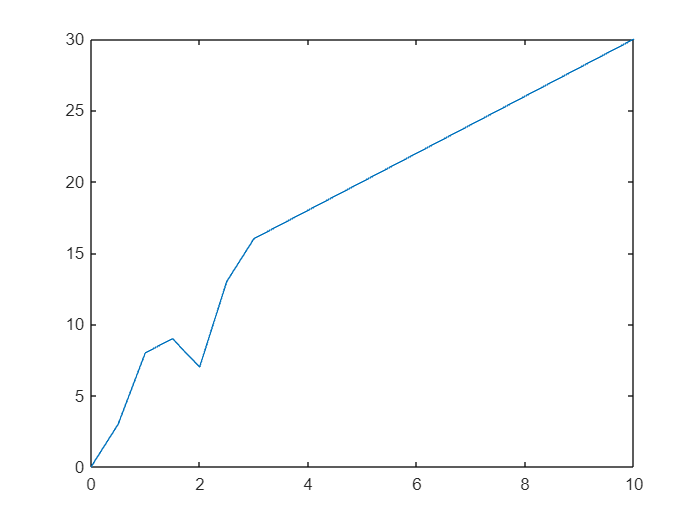

plot(tempT,fakeV)